posns = [-0.75, -0.5;
         -0.75, -1.5;
         -0.5, -2.5;
         0, 0;
         0, -2;
         0, -2.5;
         0.25, -2.6
         0.5, -1.5;
         0.75, -1.85;
         1.5, 0;
         1.5,  -1.25;
         1.5, -2.5;
         1.5, -2.5;
         1.89, -2];
thetas = repelem(0, length(posns), 1);

reps = 2

reps = 2

structs_scans = collectScans_modified(posns, thetas, reps);

Ros already initialized
Shutting down global node /matlab_global_node_75158 with NodeURI http://bf01-latitude:44395/


save('scans_total', "structs_scans")

load scans_total.mat

points_world_frame = zeros(3, numel(structs_scans(1).theta_all), length(structs_scans));
for i = 1 : length(structs_scans)
    struct_scan = structs_scans(i);
    posn = struct_scan.posn;
    heading = struct_scan.heading;
    
    points_world_frame(:, :, i) = transform_scan(struct_scan.r_all, struct_scan.theta_all, posn, heading);
end

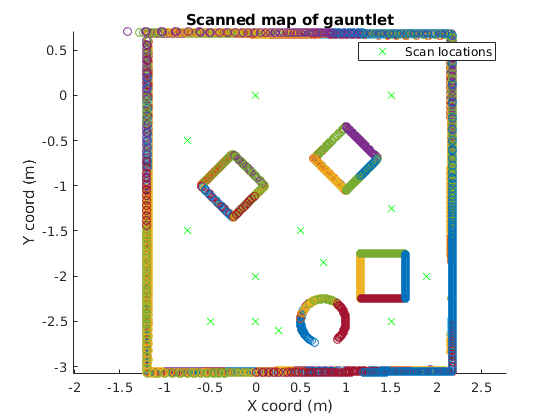

figure();
hold on;
plot(posns(:,1),posns(:,2),'gx')
axis equal;
for i = 1 : size(points_world_frame, 3)
    scatter(points_world_frame(1, :, i), points_world_frame(2, :, i))
end
legend("Scan locations")

title("Scanned map of gauntlet")
xlabel("X coord (m)")
ylabel("Y coord (m)")

function points_world_frame = transform_scan(r_all, theta_all, neato_pos, neato_theta)
% Rotation matrix in 2d projective space
f_2dproj_rotmat = ...
    @(theta) ([cos(theta), -sin(theta), 0; ...
               sin(theta),  cos(theta), 0; ...
               0         ,  0         , 1;]);

% Translation matrix in 2d projective space
f_2dproj_transmat = ...
    @(x, y) ([1 0 x; ...
              0 1 y; ...
              0 0 1;]);

% Reshape matrices of individual scans into combined vector
r_all = r_all(:)';
theta_all = theta_all(:)';

% Lidar offset: -0.084
% Given: Neato to Lidar
R_LN = eye(3);
T_LN = f_2dproj_transmat(0.084, 0);

% Find Lidar to Neato via inversion
R_NL = inv(R_LN);
T_NL = inv(T_LN);

% Given: World to Neato
R_NG = f_2dproj_rotmat(-neato_theta);
T_NG = f_2dproj_transmat(-neato_pos(1), -neato_pos(2));

% Find Neato to World via inversion
R_GN = inv(R_NG);
T_GN = inv(T_NG);

points_neato_frame = [r_all .* cos(theta_all); r_all .* sin(theta_all)];
points_world_frame = T_GN * R_GN * T_NL * R_NL * [points_neato_frame; ones(1, size(points_neato_frame, 2))];
end